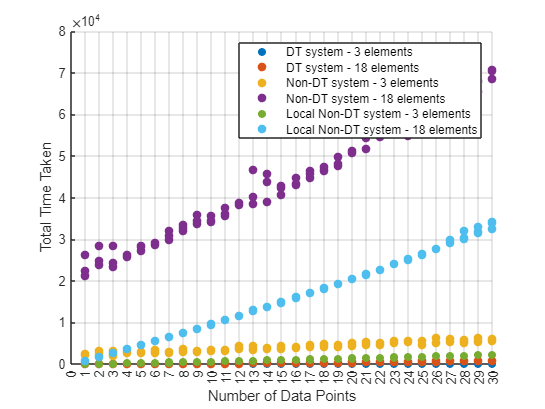

DT_Agg_Multiple = readtable("DT_Aggregate_Multiple_Data.csv", 'VariableNamingRule','preserve');
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 3,:);
scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled"), hold on
DT_Agg_Multiple_Process = DT_Agg_Multiple(DT_Agg_Multiple.("Number of DTs") == 18,:);
scatter(DT_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerEdgeColor","flat","MarkerFaceColor","flat")
Conv_Agg_Multiple = readtable("Conv_Aggregate_Multiple_Data.csv",'VariableNamingRule','preserve');
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 3,:);
scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerEdgeColor","flat","MarkerFaceColor","flat")
Conv_Agg_Multiple_Process = Conv_Agg_Multiple(Conv_Agg_Multiple.("Number of DTs") == 18,:);
scatter(Conv_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerEdgeColor","flat","MarkerFaceColor","flat")
Local_Agg_Multiple = readtable("Local_Conv_Aggregate_Multiple_Data.csv", 'VariableNamingRule','preserve');
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 3,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled")
Local_Agg_Multiple_Process = Local_Agg_Multiple(Local_Agg_Multiple.("Number of DTs") == 18,:);
scatter(Local_Agg_Multiple_Process,"Number of Data Points","Total Time Taken","filled","MarkerEdgeColor","flat","MarkerFaceColor","flat"), hold off
legend('DT system - 3 elements','DT system - 18 elements','Non-DT system - 3 elements','Non-DT system - 18 elements','Local Non-DT system - 3 elements','Local Non-DT system - 18 elements')
set(gca,'xtick',linspace(0,30,31))
set(gca,'ytick',linspace(0,8000,80000))
grid on